clearvars;

## Image Source Method

We excecute the ims method now for a grid of measurement points.

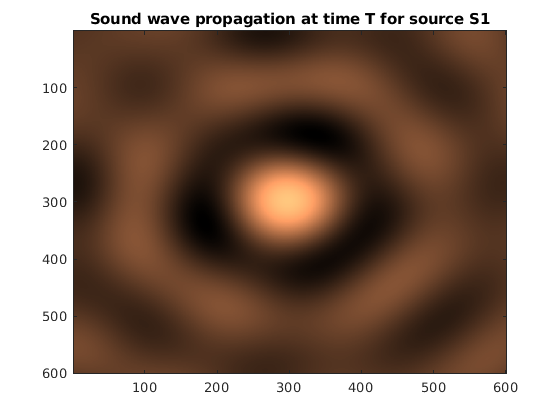

beta = 1;
L = [6,6,5]; spacing = 0.01;
f = 200; c = 343; omega = 2*pi*f; phase = 0; mag = 1;
nx = L(1); ny=L(2); nz = L(3);
S1 = [0;0;0];
alpha = [0.5,0.9,0.5,0.9,0.5,0.5];
order = 1;
wave = zeros(L(2)/spacing+1,L(1)/spacing+1);
ry = -ny/2:spacing:ny/2;
rx = -nx/2:spacing:nx/2;
parfor idy=1:ny/spacing+1
    wavex = zeros(1,nx/spacing+1);
    for idx=1:nx/spacing+1
        wavex(idx) = ISM(S1,[rx(idx);ry(idy);0],L,mag,phase,omega,c,alpha,order);
    end 
    wave(idy,:) = wavex;
end
figure;
imagesc(imag(wave)); colormap copper;
title("Sound wave propagation at time T for source S1");

Lets add a second source, just to see what the output is

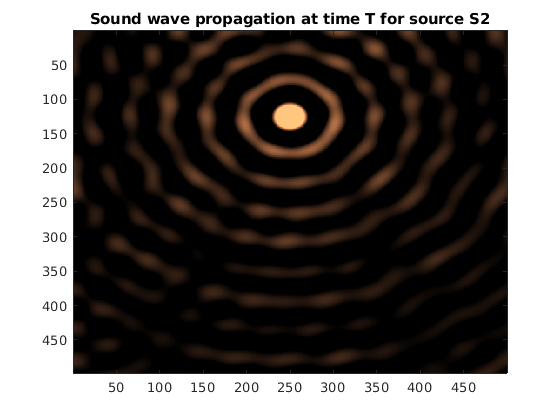

S2 = [round(n/4),n/2,n/2];
p2 = zeros(n-1,n-1);

for x=1:n-1
    for y=1:n-1
        p2(x,y) = ISM(S2,[x,y,n/2],L,phase,omega,c,alpha,order,spacing);
    end
end
figure;
colorScale = mean(mean(imag(p2(abs(p2) ~= inf))));
image(imag(p2)/colorScale); colormap copper;
title("Sound wave propagation at time T for source S2");

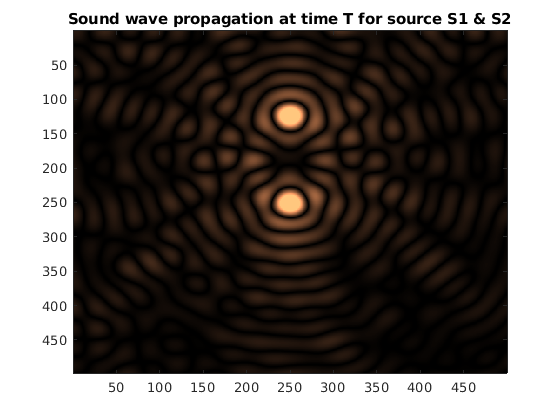

p = p1+p2;
figure;
colorScale = mean(mean(imag(p(abs(p) ~= inf))));
image(abs(imag(p))/colorScale); colormap copper;
title("Sound wave propagation at time T for source S1 & S2");